## Multipath FIR Filter

h_mp = [1 0 .9 0 0 .5 0 0 0 0 .2];
n = 100

n = 100

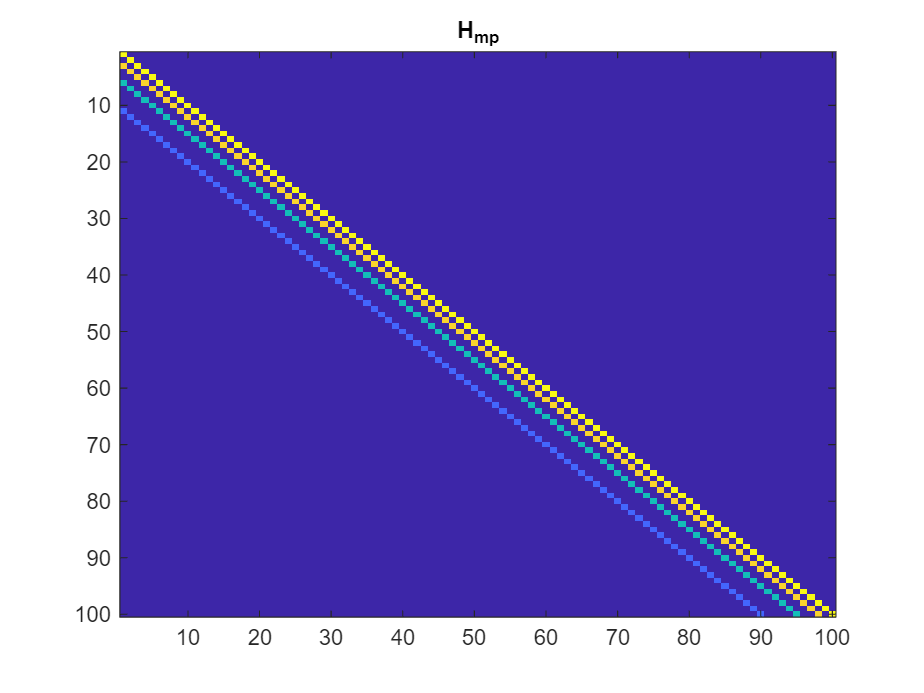


H_mp = lower_shifted_matrix_square(h_mp,n);
figure; imagesc(abs(H_mp))
title('H_{mp}')

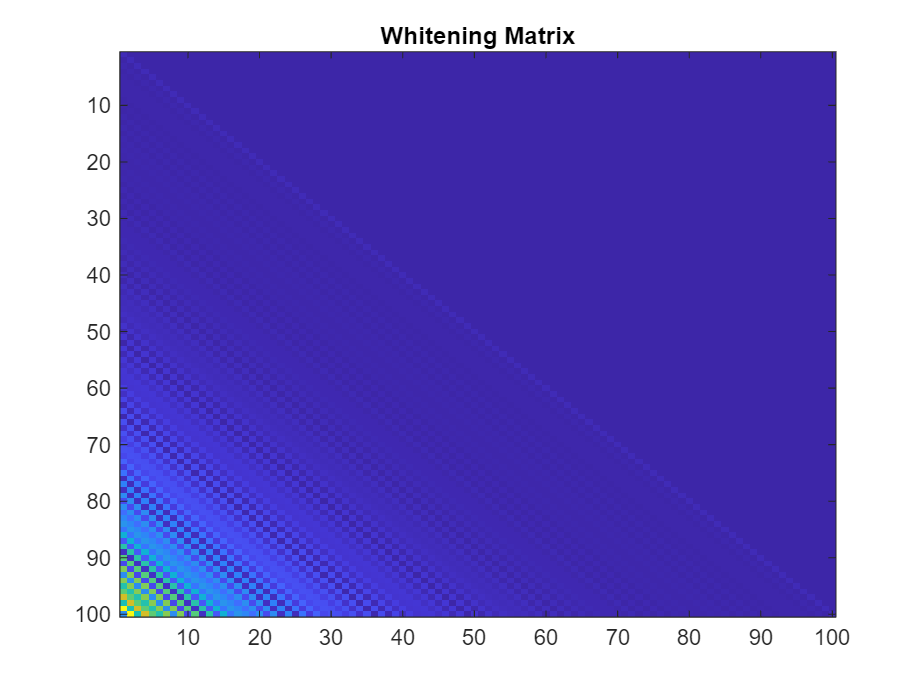

H_w = H_mp^(-.5);
figure; imagesc(abs(H_w))
title('Whitening Matrix')

## Target Response

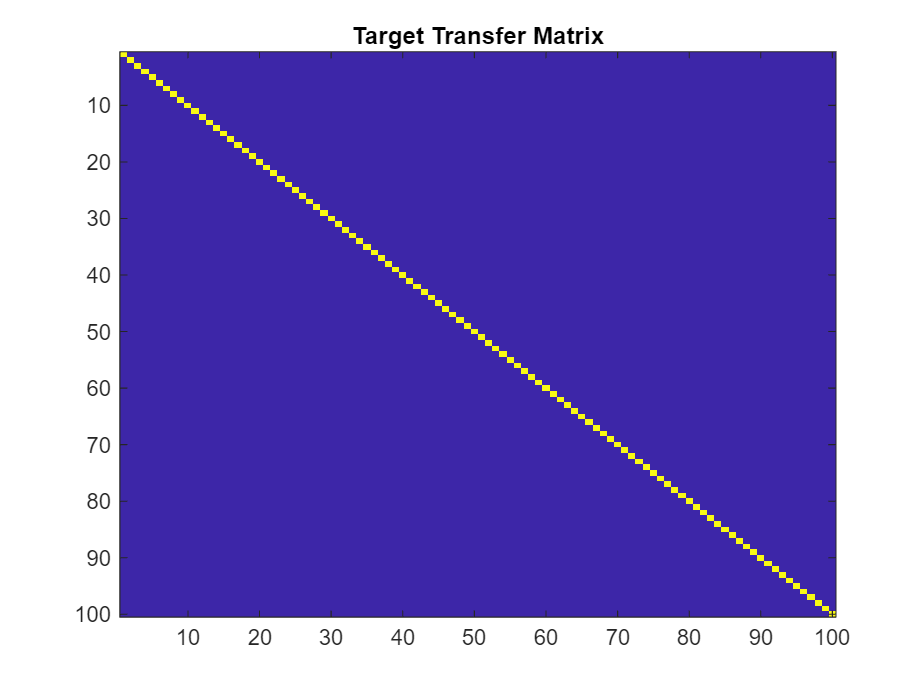

function M = main_and_sub_diag(n)
    M = eye(n);                 % Main diagonal
    M = M + diag(ones(n-1,1), -1); % Subdiagonal below main
end

H_t = eye(n); % point target
% H_t = main_and_sub_diag(n);
figure; imagesc(abs(H_t))
title('Target Transfer Matrix')

## Composite Channel Transfer Matrix

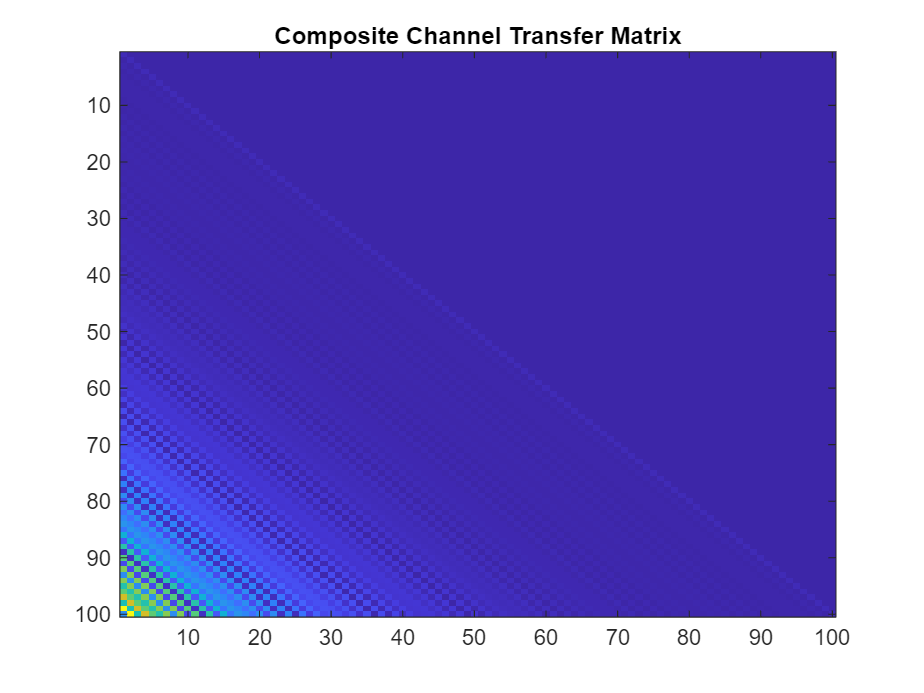

H = H_w * H_t;
figure; imagesc(abs(H))
title('Composite Channel Transfer Matrix')

## Optimal Waveform Design

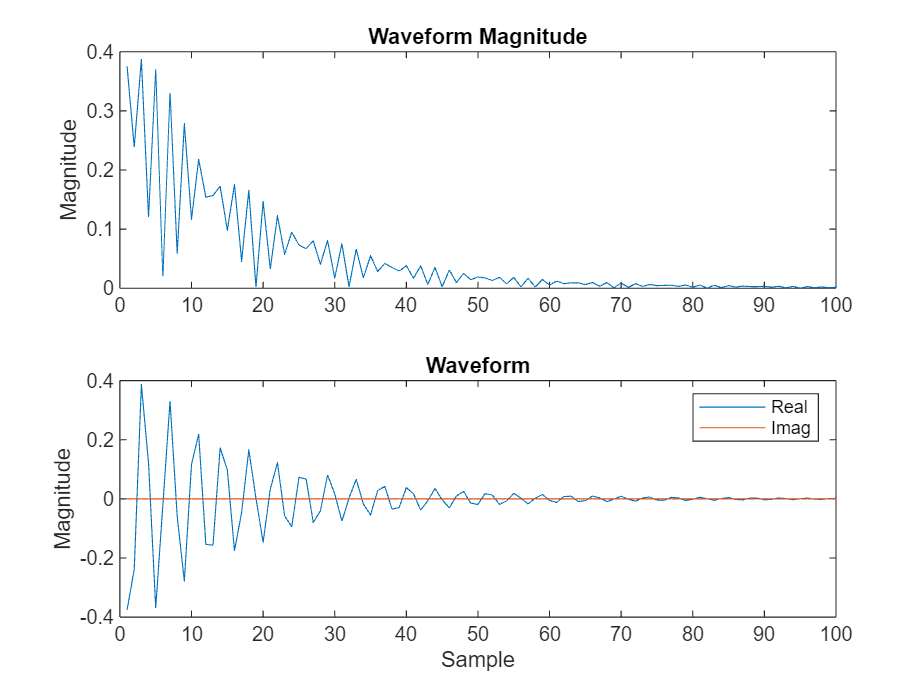

[V,D] = eig(H'*H);
[~,idx] = max(diag(D)); % find max eigenvalue
wfm = V(:,idx);
figure; 
subplot(2,1,1)
plot(abs(wfm))
title('Waveform Magnitude')
ylabel('Magnitude')
subplot(2,1,2)
plot(real(wfm))
hold on;
plot(imag(wfm))
title('Waveform')
legend({'Real','Imag'})
xlabel('Sample')
ylabel('Magnitude')

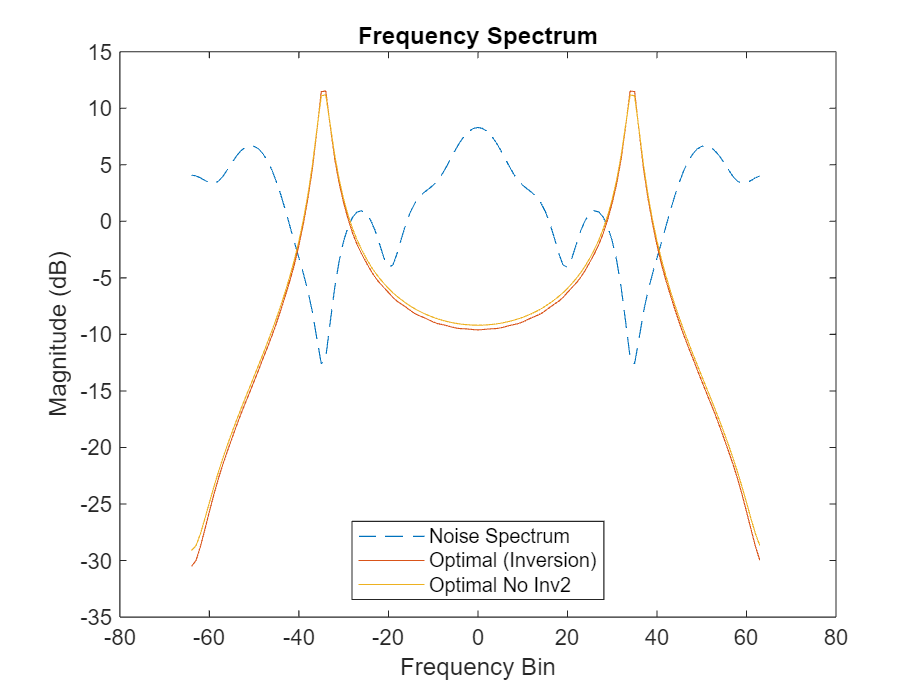


nfft = 128;
f = -nfft/2:(nfft/2-1);
figure;
plot(f,mag2db(abs(fftshift(fft(h_mp,nfft)))),'--','DisplayName','Noise Spectrum')
hold on;
plot(f,mag2db(abs(fftshift(fft(wfm,nfft)))),'DisplayName','Optimal (Inversion)')
hold on;

legend('Location','south')
% Verifying the optimal is also the min eigenvector of the uninverted cov
% matrix
[V_min,D_min] = eig(H_mp'*H_mp);
[~,idx] = min(diag(D_min));
% figure; plot(abs(V_min(:,idx)))
plot(f,mag2db(abs(fftshift(fft(V_min(:,idx),nfft)))),'DisplayName','Optimal No Inv2')
title('Frequency Spectrum')
ylabel('Magnitude (dB)')
xlabel('Frequency Bin')

## Comparison with LFM Waveform

if n == 100
    lfm = phased.LinearFMWaveform('SweepBandwidth',1e5,...
        'OutputFormat','Pulses','SampleRate',1e5,'SweepInterval','Symmetric',...
        'PulseWidth',500e-6,'PRF',10e2,'NumPulses',1);
    tb = lfm.PulseWidth*lfm.bandwidth;
    lfm_array = .25*lfm();
else
    lfm = phased.LinearFMWaveform('SweepBandwidth',1e5,...
        'OutputFormat','Pulses','SampleRate',2.2e5,'SweepInterval','Symmetric',...
        'PulseWidth',5e-5,'PRF',2e4,'NumPulses',1);
    tb = lfm.PulseWidth*lfm.bandwidth;
    lfm_array = .25*lfm();
end
disp(['Time-bandwidth product: ', num2str(tb)])

Time-bandwidth product: 50


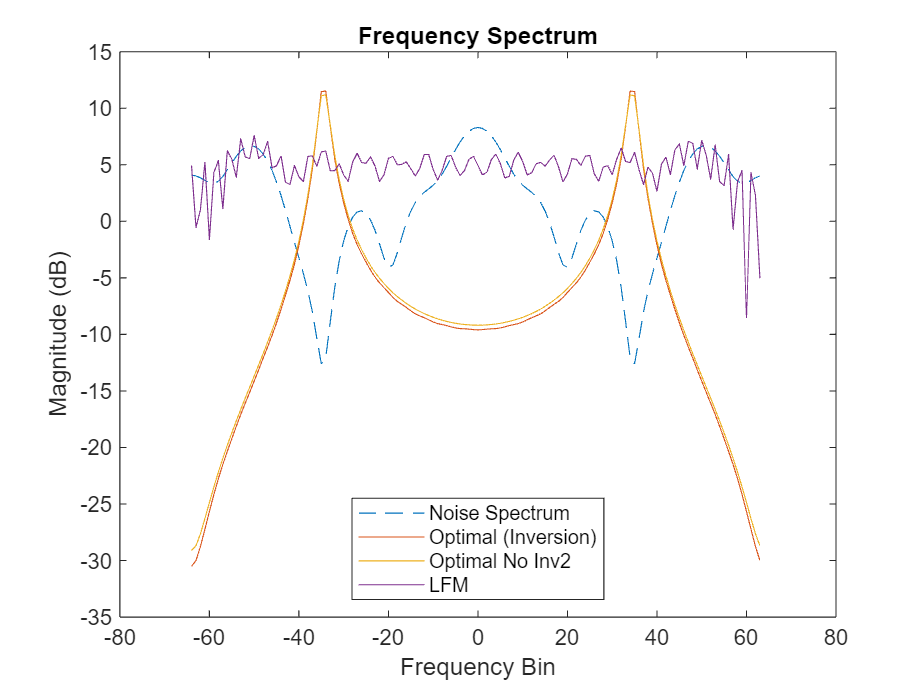

plot(f,mag2db(abs(fftshift(fft(lfm_array,nfft)))),'DisplayName','LFM')

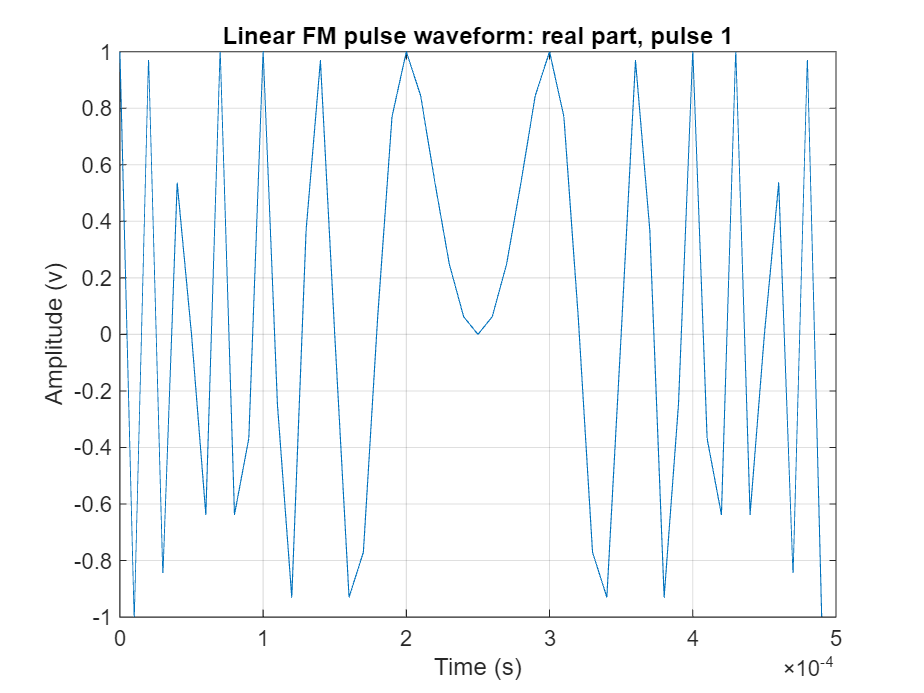

figure; plot(lfm)

% title('LFM Waveform')

% Helpers

function S = lower_shifted_matrix_square(v, N)
    % Ensure v is a column vector
    v = v(:);
    len_v = length(v);
    S = zeros(N,N); % Preallocate output

    for j = 1:N
        % Number of elements from v that can fit in this column
        num_to_copy = min(len_v, N-j+1);
        if num_to_copy > 0
            S(j:j+num_to_copy-1, j) = v(1:num_to_copy);
        end
    end
end